# Numerical Methods for Optimization and Control Theory

## Assignment 1 - Daniel Kuknyo

Tasks assigned: 2, 5, 7, 13

## 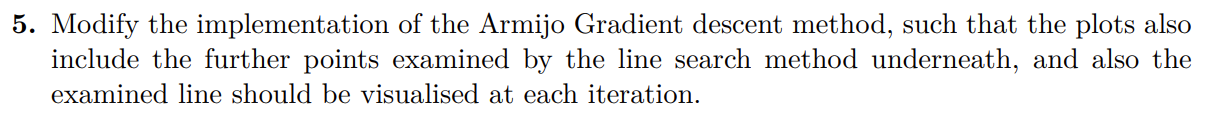

On the following plot, the green dots will correspond to the points inspected by the method, and the colorful lines are the inspected lines.

f = @(x) x.^4;
df = @(x) 4*x.^3;
ddf = @(x) 12*x.^2;

x = plot_method_armijo(@Armijo_Gradient_Descent, f, df, ddf, 20, 1.2, -1.5, 1.5, 256);

### Functions

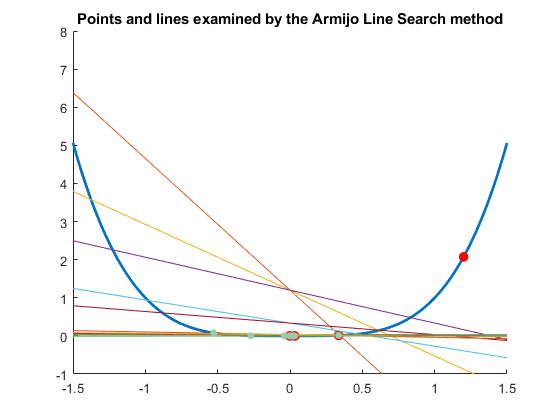

function x = plot_method_armijo(G, f, df, ddf, testpts, startpt, a, b, res)
    X = linspace(a, b, res);
    Y = f(X);
    x = [startpt];
    pts = [];
    lns = [];

    
    % Collect the points, examined points and examined points 
    for k=1:testpts
        [xk, points, lines] = G(f,df,ddf,startpt,a,b,k);
        x = [x xk];
        pts = [pts; points];
        lns = [lns; lines];
    end
    
    figure; hold on;
    plot(X, Y, 'LineWidth', 2); % Plot the function itself
    plot(x, f(x), '.', 'MarkerSize', 25, 'MarkerEdgeColor', 'red', ...
        'MarkerFaceColor', [1 .6 .6]); % Plot the points 
    
    % Plot the lines examined by the line search method
    for i=1:size(lns, 1)
        b0 = lns(i, 1);
        b1 = lns(i, 2);
        linefn = @(x, b0, b1) b0 + b1*x;
        plot(X, linefn(X, b0, b1));
    end
    
    % Plot the points examined by the line search method
    for i=1:size(pts, 1)
        plot(pts(i), f(pts(i)), '.', 'MarkerSize', 18, 'MarkerEdgeColor', [.6 .8 .66], ...
            "MarkerFaceColor", [.38 .51 .31]);
    end
    
    % Some extra settings for the plots
    xlim([a b]);
    ylim([-1 8]);
    title('Points and lines examined by the Armijo Line Search method');
    hold off;
end

function [x, points_t, lines_t] = Armijo_Gradient_Descent(f,df,~,x0,~,~,iter)
    rho = 0.5; % Step length multiplier 
    c = 0.2;   % Sufficient decrease condition 
    alpha = 1; % Initial step length
    
    points_t = [];
    lines_t = [];
    
    x = x0;
    for k = 1:iter
        p = -df(x); 
        % Step length ---- Armijo LS examines further points 
        [gamma, points, lines] = Armijo_LS(f, df, p, x, alpha, rho, c); 
        x = x + gamma * p;
        points_t = [points_t; points];
        lines_t = [lines_t; lines];
    end
end

function [alpha, points, lines] = Armijo_LS(f, df, p, x0, alpha, rho, c)
    f0 = f(x0);
    g0 = df(x0);
    x = x0 + alpha .* p;
    fk = f(x);
    dp = (g0'*p); % Directional derivative at x0
    
    points = [];
    lines = [];
    
    % Repeat until the Armijo conditions are satisfied
    while fk < f0 + c * alpha * dp
      alpha = alpha / rho;
      x = x0 + alpha * p;
      fk = f(x);
      
      points = [points; x];
      lines = [lines; x0 alpha*p];
    end
    
    while fk > f0 + c * alpha * dp
      alpha = rho * alpha;
      x = x0 + alpha * p;
      fk = f(x);
      
      points = [points; x];
      lines = [lines; x0 alpha*p];
    end
end